# Kmeans segmentation

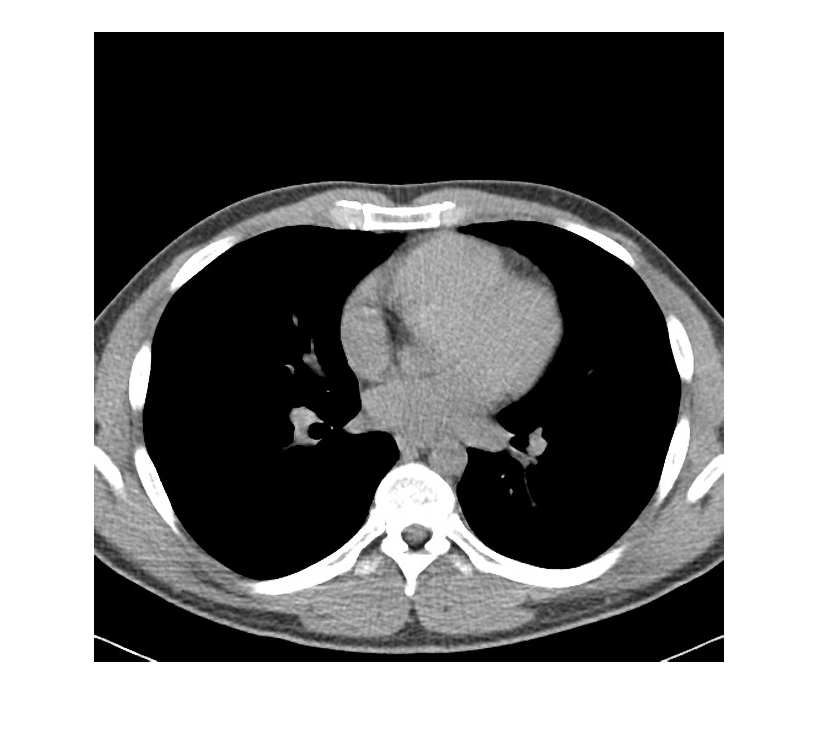

f = imread('CT_CHEST.jpg');
f = double(f(:,:,1));
f = f/max(max(f));
imshow(f)

% Robets op
dxp = [0,1;-1,0];
dyp = [1,0;0,-1];

Kmeans

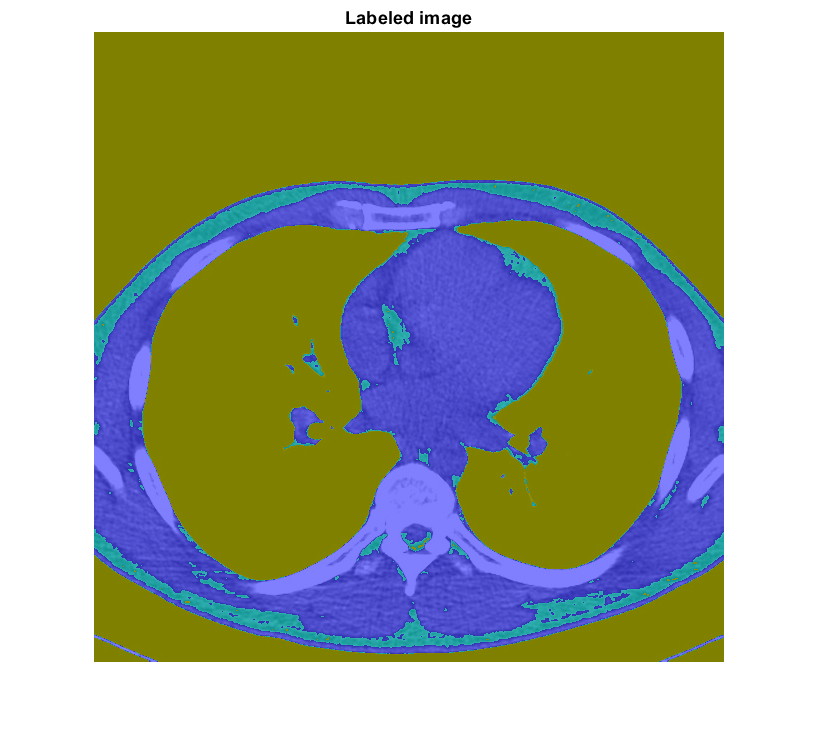

% 4 class
[L,Centers] = imsegkmeans(int8(255*f),3);
B = labeloverlay(f,L);
[L1,centers1] = imsegkmeans(int8(255*f),5);
B1 = labeloverlay(f,L1);

figure
imshow(B)
title('Labeled image')

Clean wih morphology each class

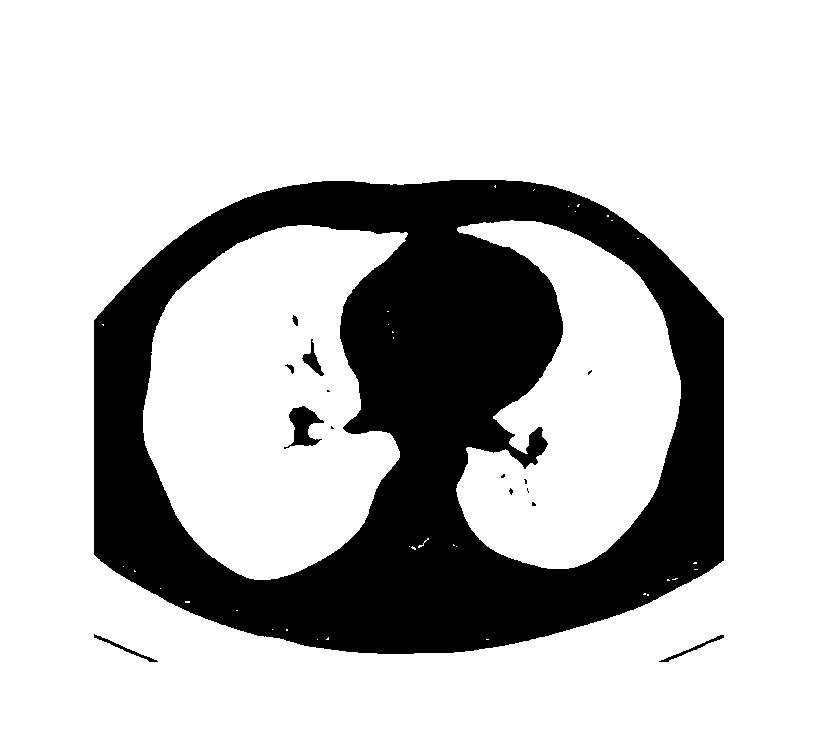

% First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)

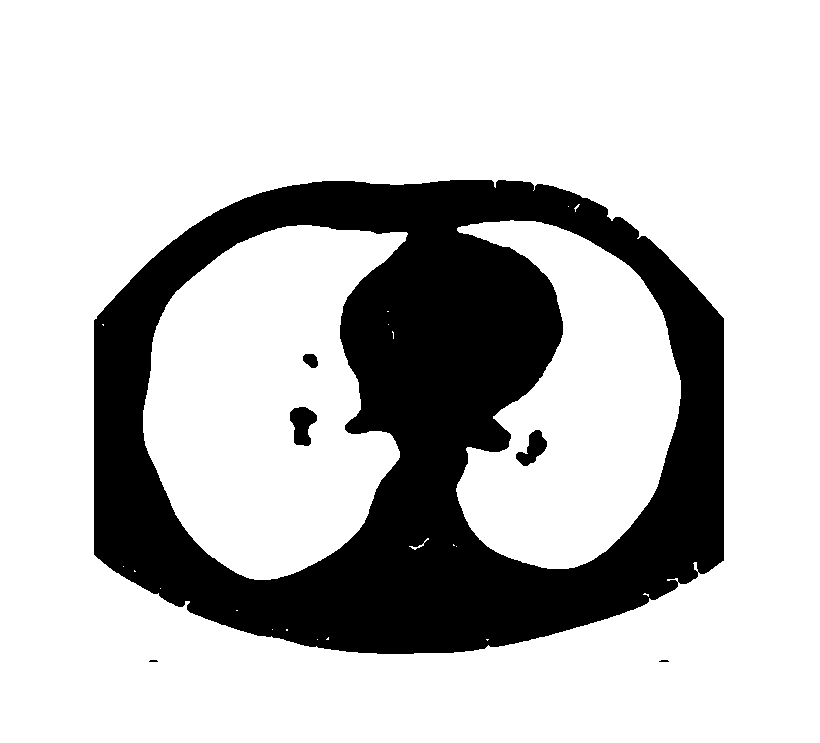

% Remove false positives with imclose
diskse = strel('disk',5);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)

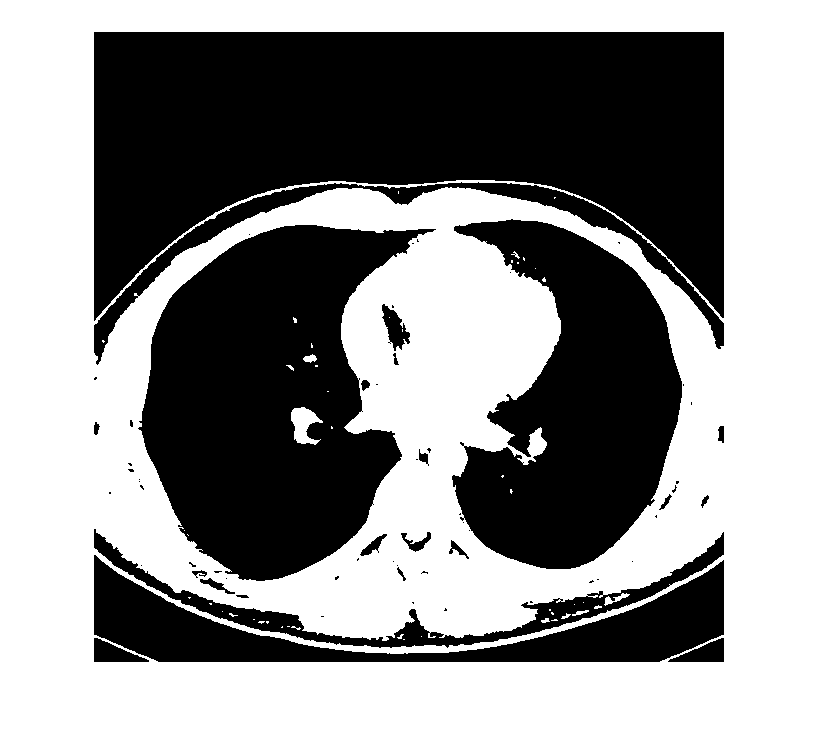


% Second label
label_two = L == 2;
imshow(label_two)

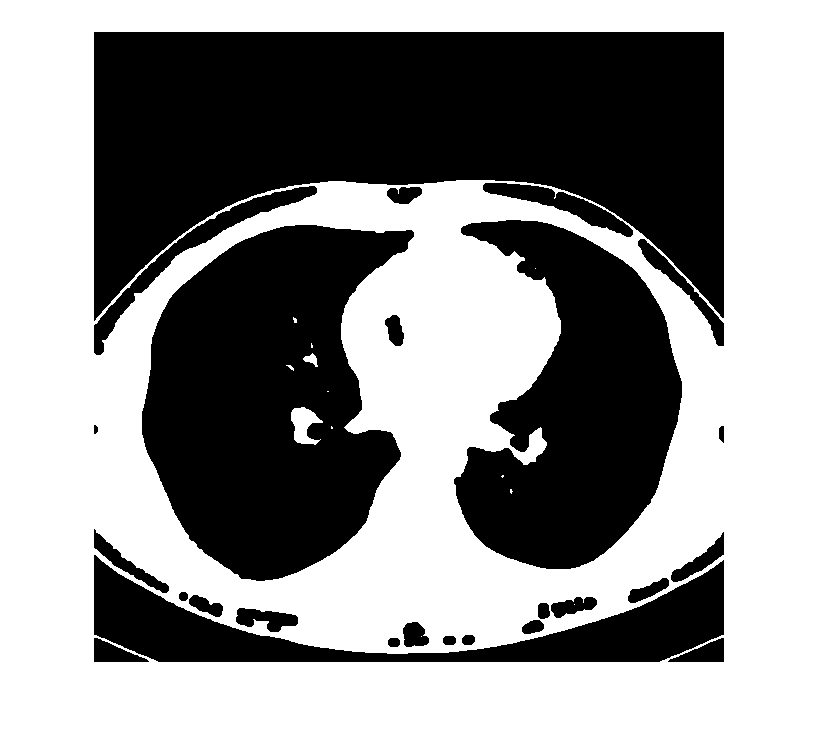

% Remove false positives with imclose
label_close_two = imclose(label_two,diskse);
imshow(label_close_two)

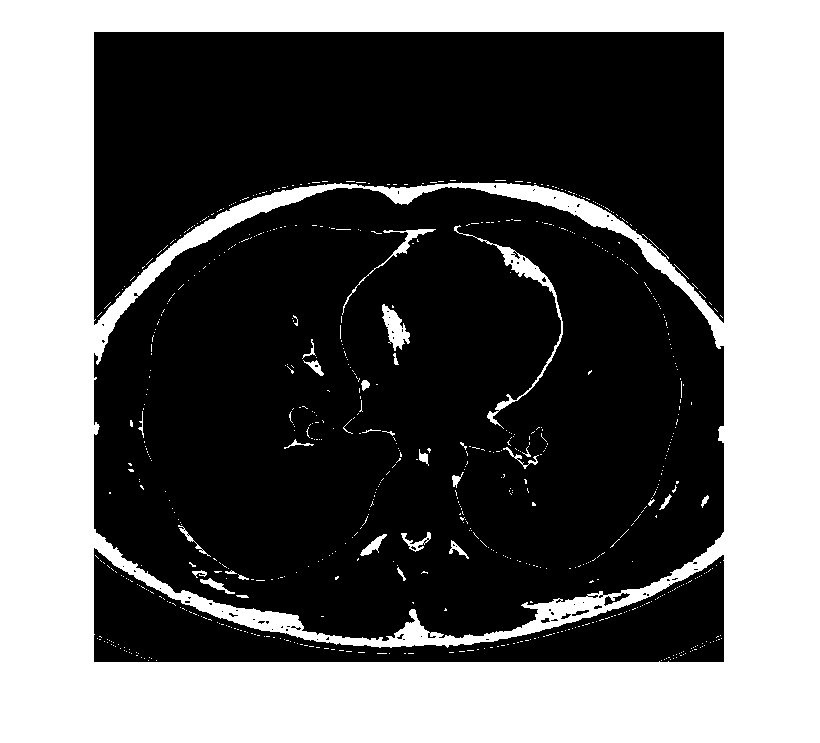


% Third label
label_three = L == 3;
imshow(label_three)

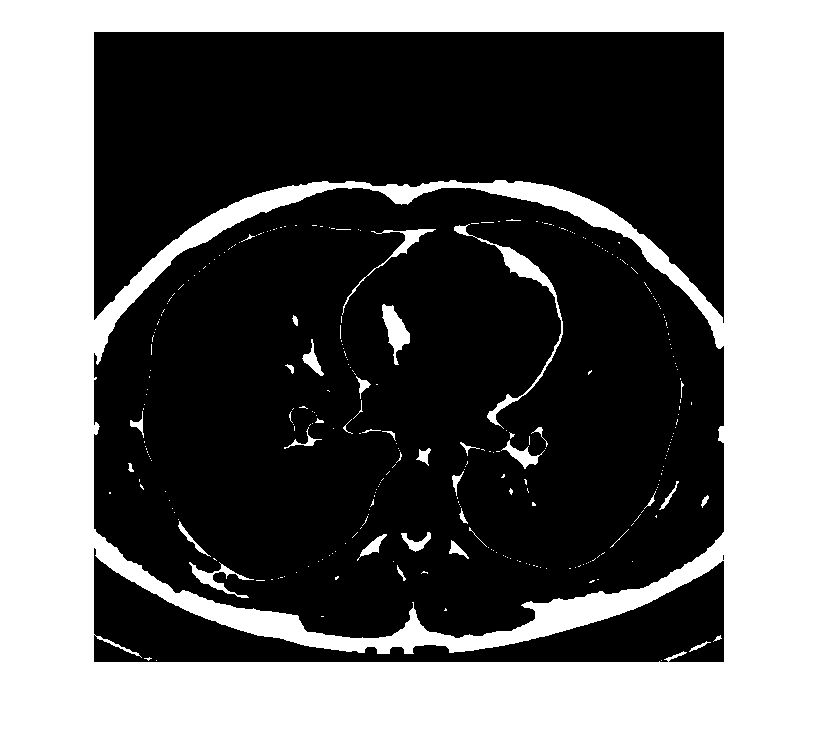

% Remove false positives with imclose
label_close_three = imclose(label_three,diskse);
imshow(label_close_three)


% Fourth label
label_four = L == 2;
imshow(label_four)

% Remove false positives with imclose
label_close_four = imclose(label_four,diskse);
imshow(label_close_four)

Connected components of Label 1

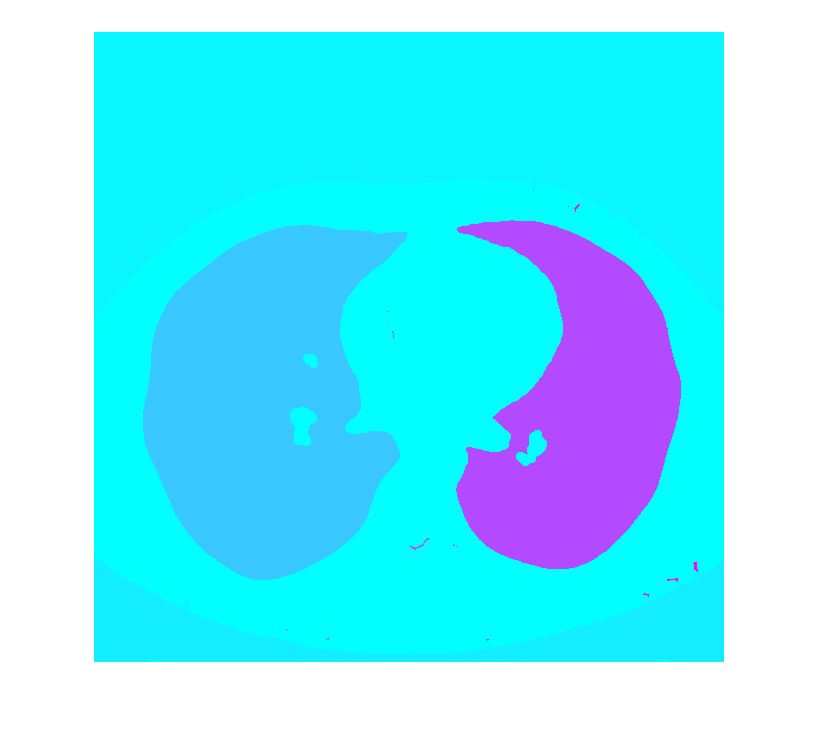

cc = bwconncomp(label_close_one,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
colormap('cool')

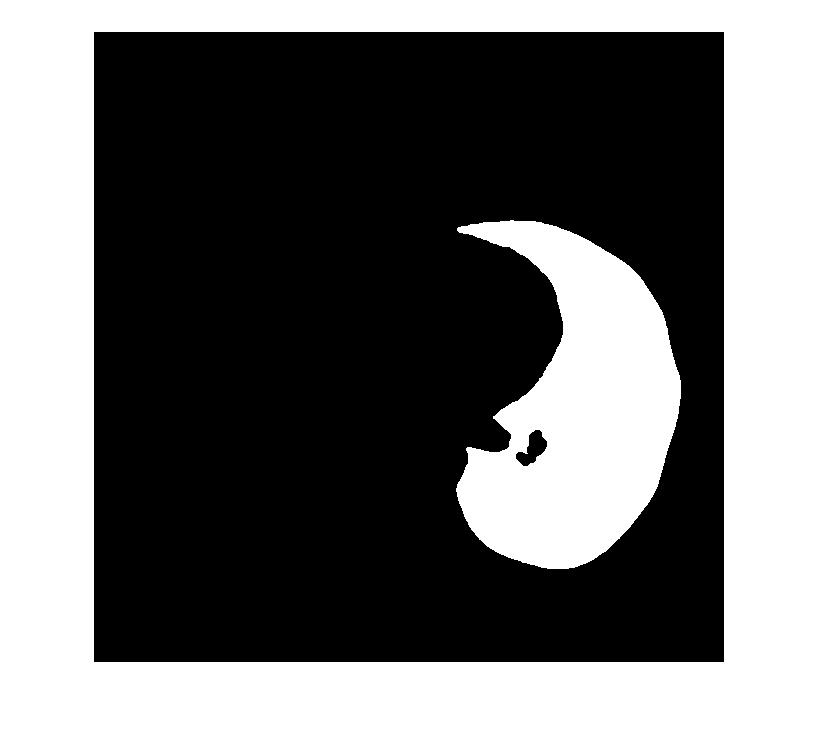


% show left lung

% Using the data tips
LungLabel = 19;
imshow(labeled==LungLabel,[]) % Buscar etiqueta (index) en plot anterior (19)

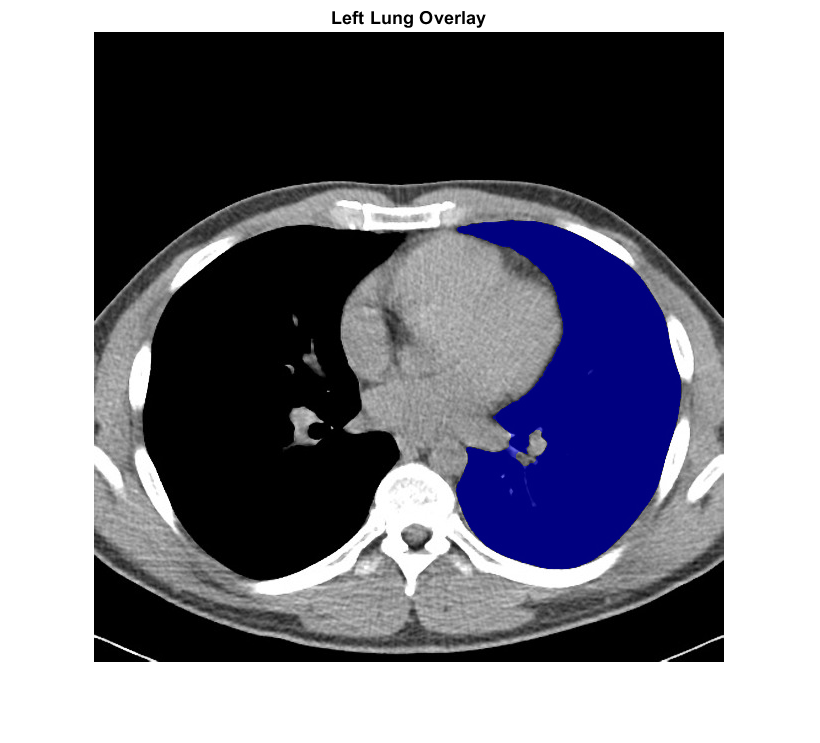

B2 = labeloverlay(f,labeled==LungLabel);
imshow(B2)
title('Left Lung Overlay')

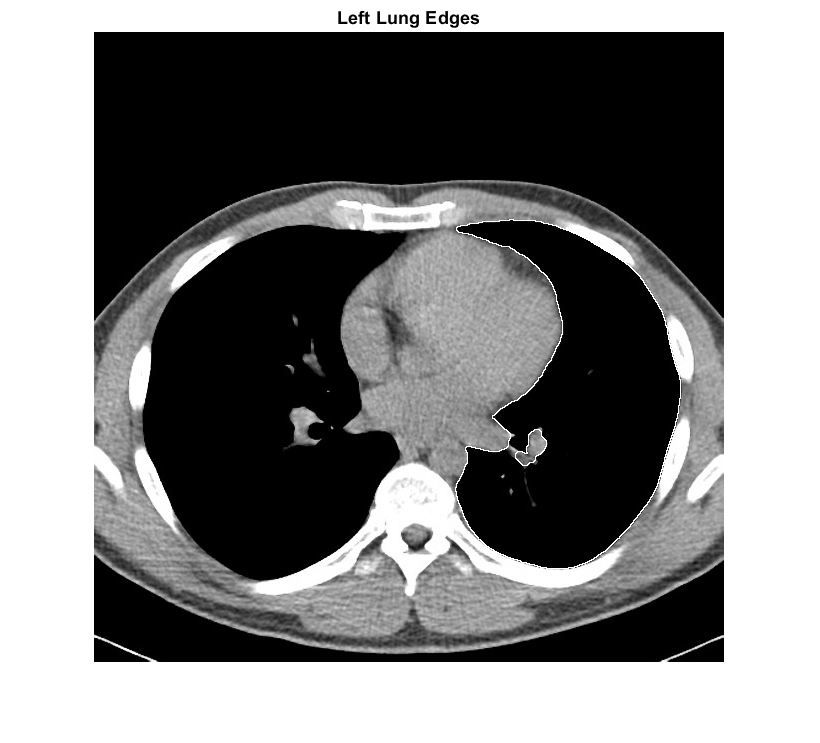


seg1 = labeled==LungLabel;
edgemap = abs(conv2(seg1,dxp,'same'))+abs(conv2(seg1,dyp,'same'));
imshow(f+edgemap,[0,1]);
title('Left Lung Edges')

Watershed

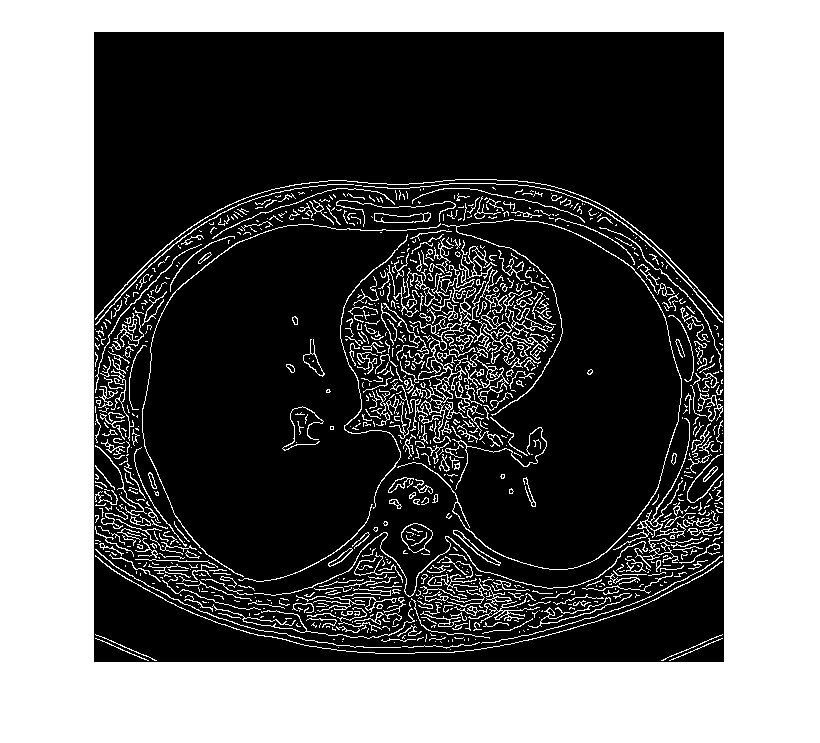

edgeC = edge(f,'Canny');
imshow(edgeC,[])

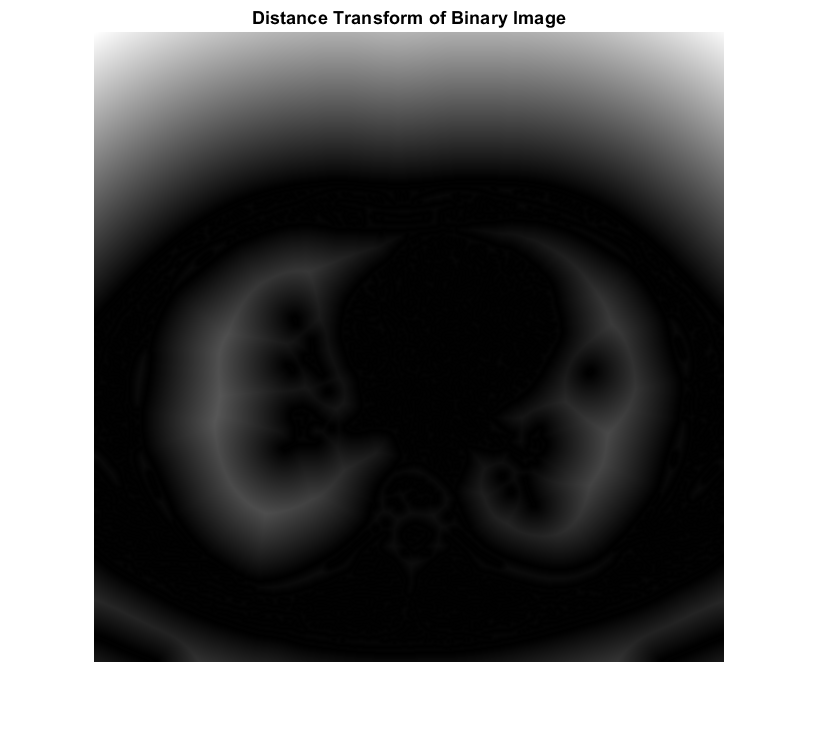

D = bwdist(edgeC);
imshow(D,[])
title('Distance Transform of Binary Image')

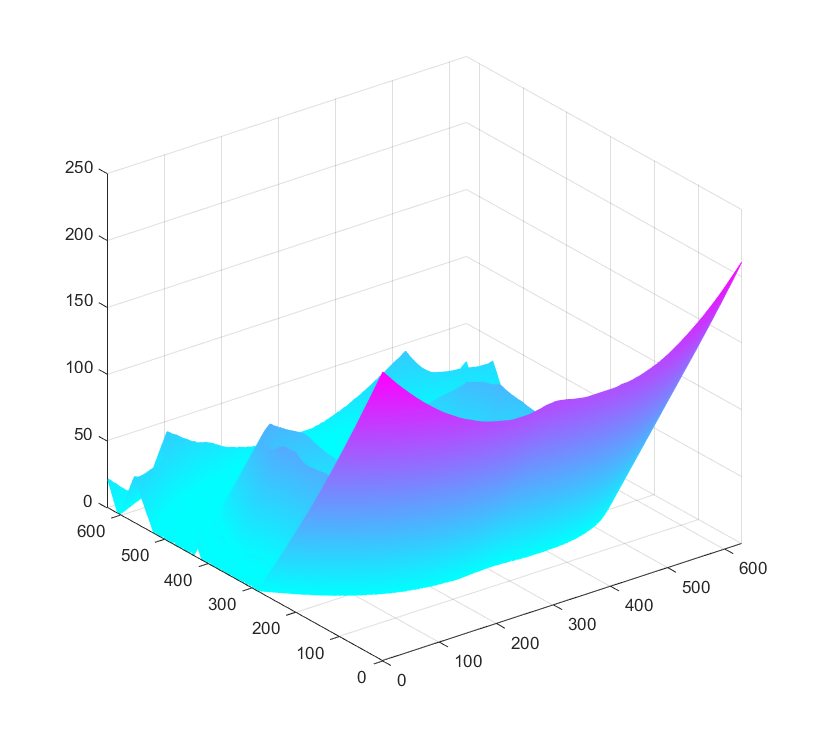

mesh(D)

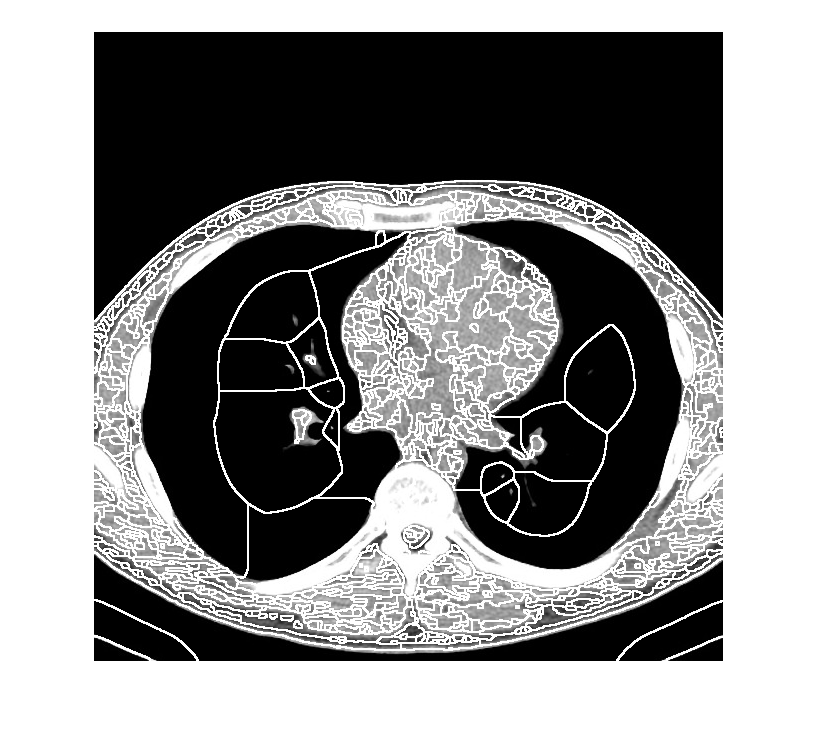

L = watershed(D);

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);

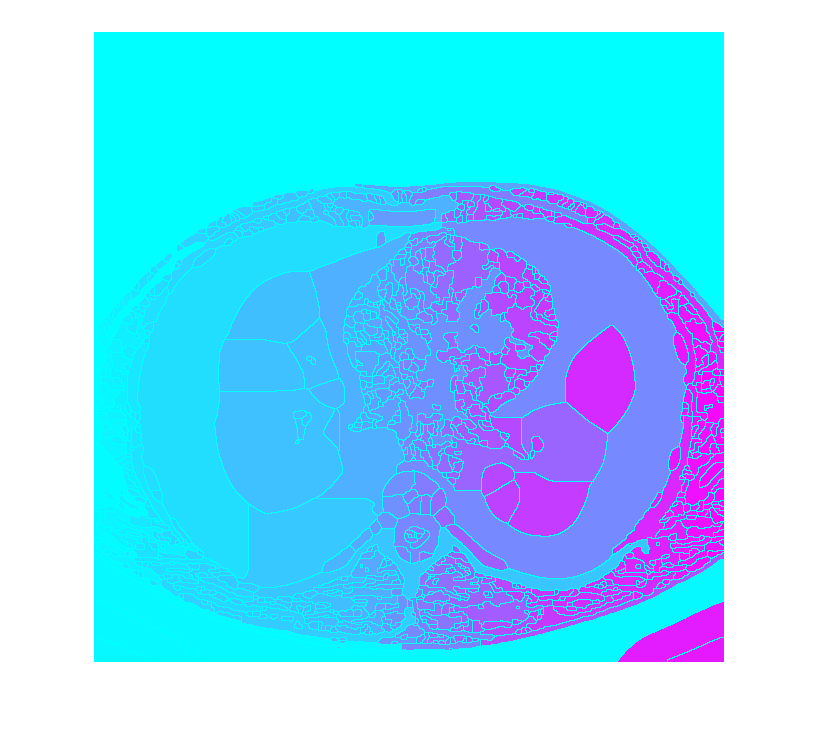


imshow(L,[])
colormap('cool')

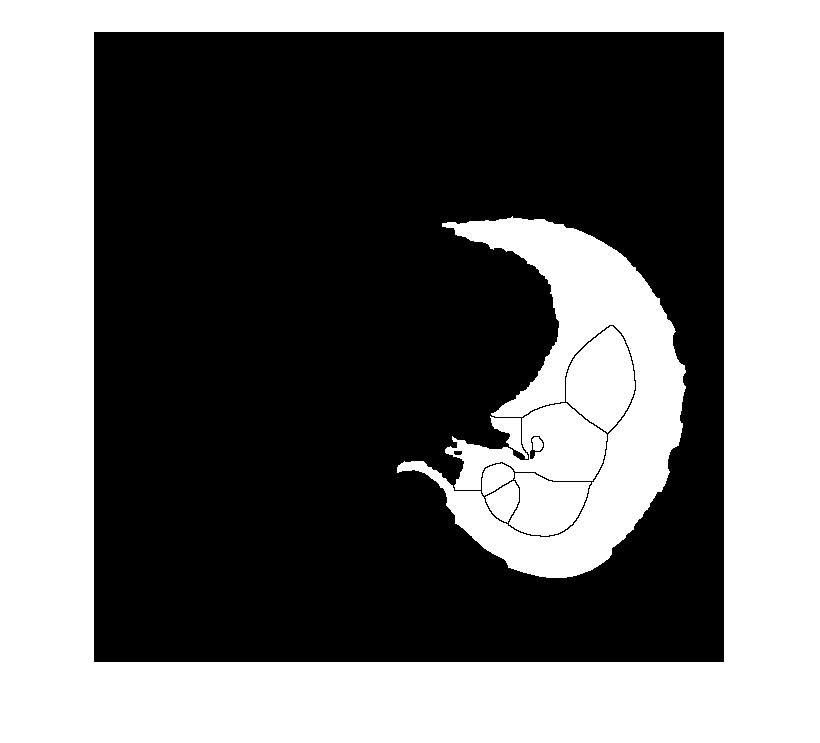


% The lung is made of several components, We must merge the labels
LeftLung = L==441 | L==795 | L==578 | L==729 | L==710 | L==683 | L==751 | L==694;
imshow(LeftLung,[])

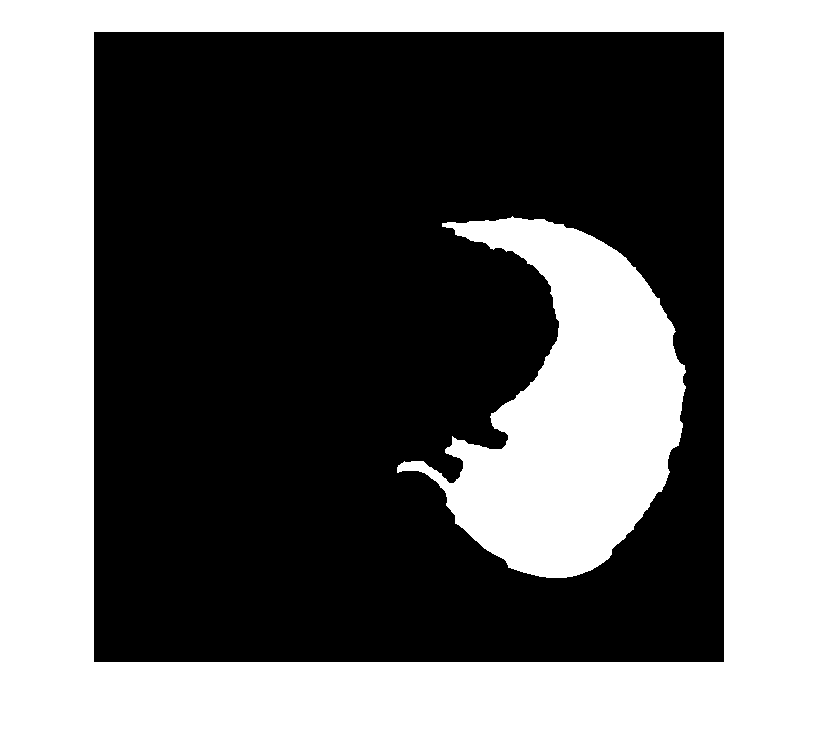


LeftLung_close = imclose(LeftLung,diskse);
imshow(LeftLung_close)

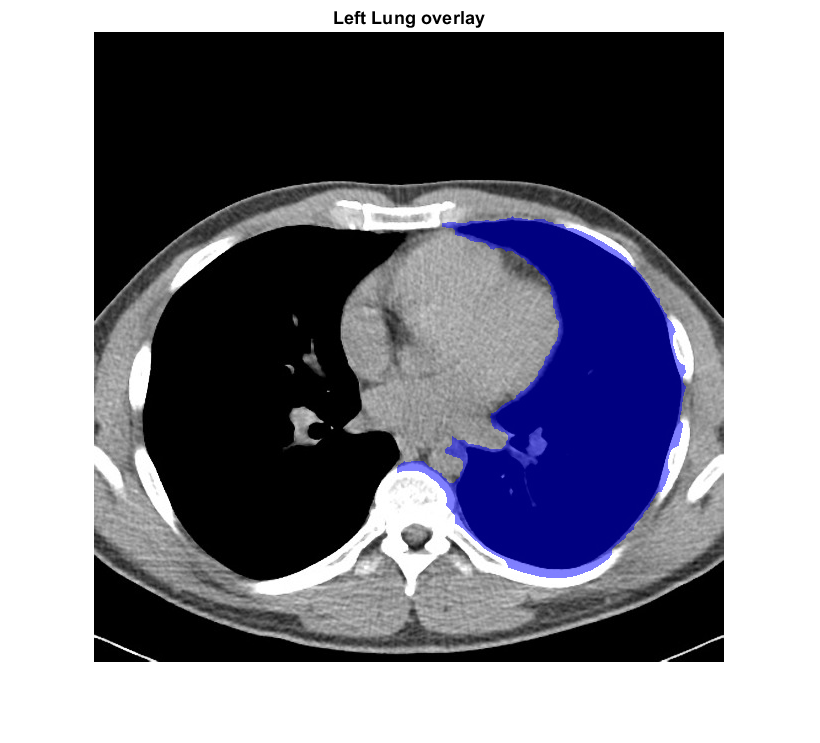


B3 = labeloverlay(f,LeftLung_close);
imshow(B3)
title('Left Lung overlay')

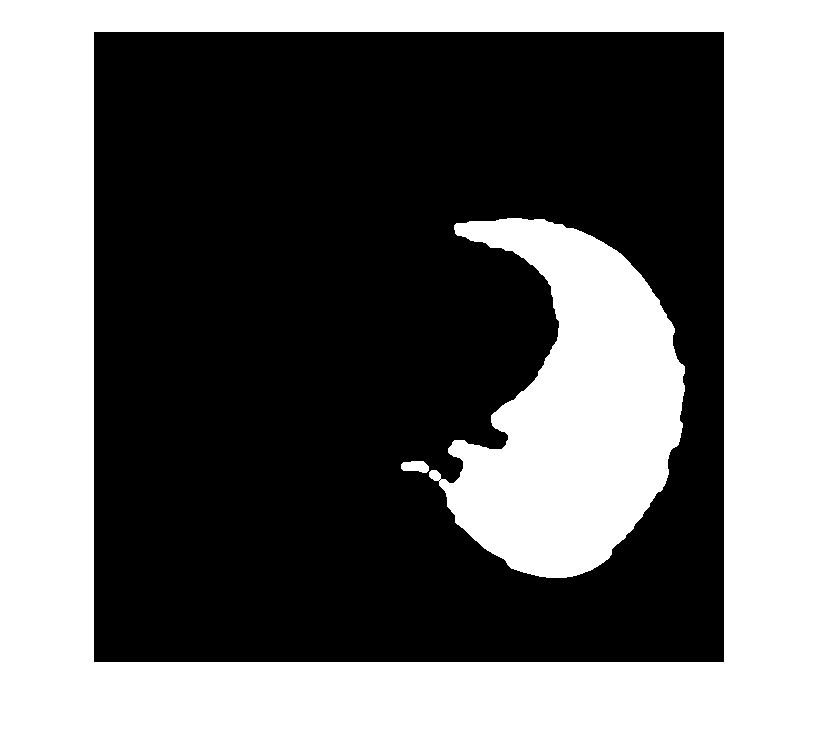


% Remove false positives with imopen
label_lung = imopen(LeftLung_close,diskse);
imshow(label_lung)

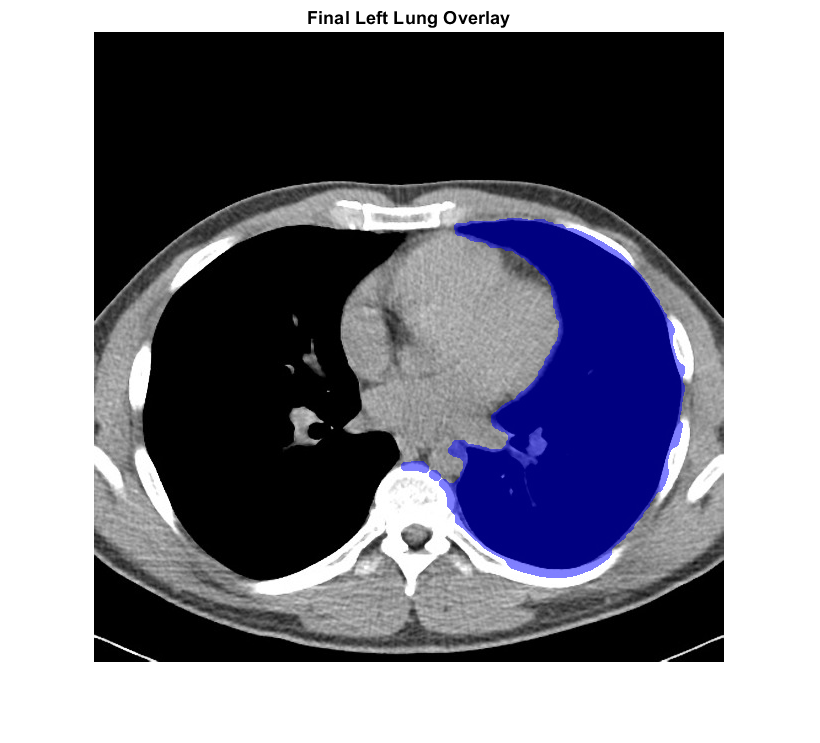


B3 = labeloverlay(f,label_lung);

imshow(B3)
title('Final Left Lung Overlay')